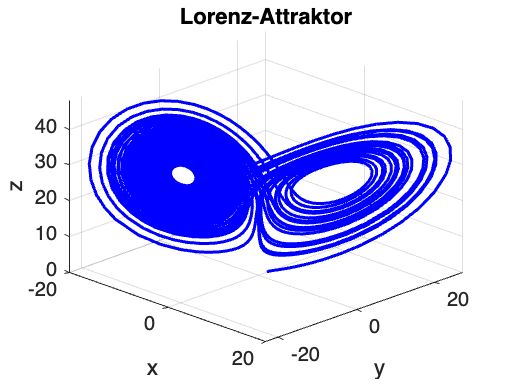

%% Lorenz-Attraktor Simulation
% In diesem Live Script simulieren wir den Lorenz-Attraktor, ein klassisches
% Beispiel für ein chaotisches System. Wir werden die Bewegung des Systems
% visualisieren und untersuchen, wie sich ein kleiner Unterschied in den
% Anfangsbedingungen auswirkt.

% Parameter des Lorenz-Systems
sigma = 10;
beta = 8/3;
rho = 28;

% Anfangswerte
initial_conditions = [1 1 1];

% Simulationszeit
t_span = [0 50];

%% Lösen der Differentialgleichungen
% Das Lorenz-System wird durch die folgenden drei gekoppelten Differentialgleichungen
% beschrieben:
%
% $$ \dot{x} = \sigma (y - x) $$
% $$ \dot{y} = x (\rho - z) - y $$
% $$ \dot{z} = xy - \beta z $$

% Definiere das Lorenz-System als Funktion
lorenz = @(t, xyz) [
    sigma * (xyz(2) - xyz(1));
    xyz(1) * (rho - xyz(3)) - xyz(2);
    xyz(1) * xyz(2) - beta * xyz(3)
];

% Löse die Differentialgleichungen numerisch
[t, xyz] = ode45(lorenz, t_span, initial_conditions);

%% Visualisierung des Lorenz-Attraktors
% Hier visualisieren wir den Lorenz-Attraktor in einem 3D-Plot.
figure;
plot3(xyz(:,1), xyz(:,2), xyz(:,3), 'b-', 'LineWidth', 1.5);
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
title('Lorenz-Attraktor');
view(45, 30);

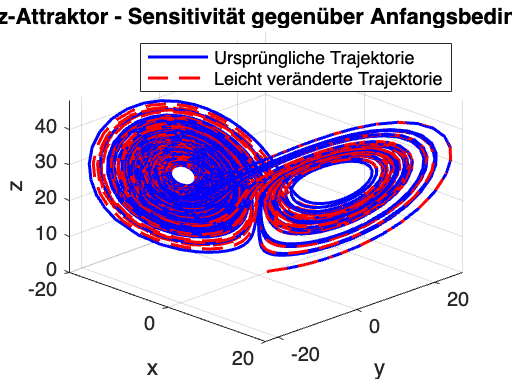


%% Sensitivität gegenüber Anfangsbedingungen
% Eine der faszinierenden Eigenschaften des Lorenz-Attraktors ist seine Sensitivität
% gegenüber kleinen Änderungen in den Anfangsbedingungen. Hier wiederholen wir die
% Simulation mit leicht veränderten Anfangsbedingungen und vergleichen die Trajektorien.

% Neue Anfangsbedingungen (leicht verschoben)
initial_conditions_2 = [1.001 1 1];

% Löse die Differentialgleichungen erneut
[~, xyz2] = ode45(lorenz, t_span, initial_conditions_2);

% Visualisierung des Vergleichs der beiden Trajektorien
figure;
hold on;
plot3(xyz(:,1), xyz(:,2), xyz(:,3), 'b-', 'LineWidth', 1.5);
plot3(xyz2(:,1), xyz2(:,2), xyz2(:,3), 'r--', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
title('Lorenz-Attraktor - Sensitivität gegenüber Anfangsbedingungen');
legend('Ursprüngliche Trajektorie', 'Leicht veränderte Trajektorie');
view(45, 30);


%% Zusammenfassung und Interpretation
% Diese Simulation zeigt, wie empfindlich das Lorenz-System auf kleine Änderungen in den
% Anfangsbedingungen reagiert. Selbst eine minimale Veränderung von 0.001 führt nach
% einiger Zeit zu völlig unterschiedlichen Trajektorien. Diese Eigenschaft ist typisch für
% chaotische Systeme und wird oft als "Schmetterlingseffekt" bezeichnet.

% Experimentiere mit den Parametern $\sigma$, $\beta$ und $\rho$, um das Verhalten des
% Systems zu erkunden!
